# Genetic Algorithim in Tandem with pattern search for a PID controller accounting for implementation cost using pole placement methods for nonlncons

%0 initialisation and set up
    %0.0 plant transfer function     
        s = tf('s');
        G = G_hat

G =
 
    693.37 (s-7.516) (s+7.516)
  ------------------------------
  s (s+1060) (s+12.58) (s+0.149)
 
Continuous-time zero/pole/gain model.




    %0.1 desired characteristics
        rise_time=0.5      %time to reach 90 percent of input 

rise_time = 0.5000

        settling_time=2   %time for signal to be within settling tolerance +/-

settling_time = 2

        peak_overshoot=20   %in percent copared to steady state value

peak_overshoot = 20

        settling_tolerance=1 %in percent

settling_tolerance = 1

    %0.2 Algorithim paramaters
        weighting_exponent=[1,1,1]      %rise time,settling time, peak overshoot ,

weighting_exponent =      1     1     1


        weighting_proportional=[1,1,1]  %rise time,settling time, peak overshoot 

weighting_proportional =      1     1     1


        weighting=[weighting_proportional;weighting_exponent]

weighting =      1     1     1
     1     1     1


        %if solution is weird then modify mutation factor and other options
        max_generations=20;
        population_size=30;
        elite_proportion=0.05;
        crossover_fraction=0.75;    %%exploitative
        mutation_factor=0.18;       %%eplorative
        max_num_tests=3               %no. times to run the algorithim 

max_num_tests = 3

        x_bound=1                %acceptable solution to stop re running more than sum of weighting is reasonable fitness ~>0.5 with weightings of 1 for rise time 

x_bound = 1

        cost=@(K) 0.6*exp((sum(abs(K))/3+sum(abs(K).^-1)/3)/20); %cost function for gain modify as required
        
        % options on the algorithim 
        options=optimoptions(@ga,"MaxGenerations",max_generations,'PopulationSize',population_size,'SelectionFcn',{@selectiontournament,4},'EliteCount',ceil(elite_proportion*population_size),'CrossoverFraction',crossover_fraction,'CrossoverFcn',@crossoverheuristic,'MutationFcn',{@mutationadaptfeasible,mutation_factor});
        x=inf;
        LB=-100*[1,1,1]';
        UB=100*[1,1,1]';
        ConstraintFunction=[]; %@(K) stable_const(K,G)

%1 algorithim implementation 
    for i=1:max_num_tests    %for the number of tests
        
        %1.1 execute combined algoritthim
            [K_test,x_test]=PID_Best(G*(-1)^(i-1),rise_time,settling_time,peak_overshoot,settling_tolerance,options,weighting,cost,LB,UB,ConstraintFunction);
        %1.2 if new test is better than old overwrite data
            if x_test<x
                K=K_test*(-1)^(i-1);
                x=x_test;
            end
        %1.3 if the new test is sufficiently good stop re running
            if x<x_bound
                number_of_iterations=i
                break
            end
    end

Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.



%2 testing output solution 
    %2.1 defining solution 
        C=K(1)+K(2)/s+K(3)*s    %controller transfer function 

C =
 
  -0.7085 s^2 - 1.008 s - 0.01138
  -------------------------------
                 s
 
Continuous-time transfer function.



        H=feedback(C*G,1)       %closed loop transfer function 

H =
 
   -491.25 (s+7.516) (s-7.516) (s+1.412) (s+0.01138)
  ----------------------------------------------------
  (s+559) (s+20.37) (s+0.01138) (s^2 + 2.423s + 3.439)
 
Continuous-time zero/pole/gain model.



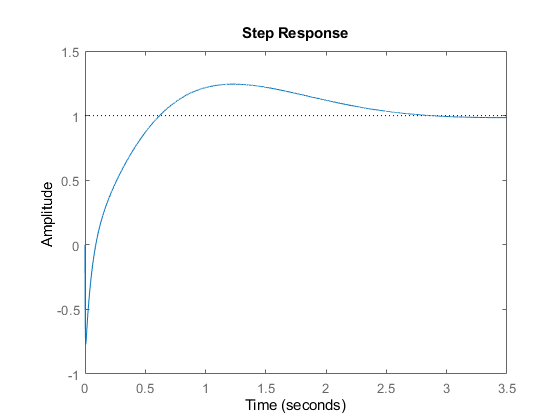

    %2.2 simulation solution 
        step(H)                 %step response

        stepinfo(H)             %step paramaters

ans = struct with fields:
        RiseTime: 0.4131
    SettlingTime: 2.4862
     SettlingMin: 0.9000
     SettlingMax: 1.2434
       Overshoot: 24.3408
      Undershoot: 77.1145
            Peak: 1.2434
        PeakTime: 1.2314


    %2.3 final fitness value
        fitness=pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K,cost)

fitness = 77.4972

function [K,x]=PID_Best(G,rise_time,settling_time,peak_overshoot,settling_tolerance,options,weighting,cost,LB,UB,ConstraintFunction)

        fitness_function=@(K)pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K,cost);

[K,~] = ga(fitness_function,3,[],[],[],[],[],[],ConstraintFunction,[],options);

[K,x] = patternsearch(fitness_function,K,-1*eye(3),-1e-6*ones(3,1));

end

function fitness=pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K,cost)
    s=tf('s');
        C=K(1)+K(2)/s+K(3)*s;
        H=feedback(C*G,1);                 %closed loop tf
        poles=pole(H);
    if any(K<0)
        flag=1;
    end
    if ~all(K)   || any(real(poles)>0)
        fitness=inf;  %dc gain of zero error or -ve error
        return
    else
        Tau=rise_time+settling_time+1;      %time period
        [Y,T]=step(H,[0:Tau/1000:5*Tau]);  %simulate the response for 5 time periods
        fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting)+cost(K);
        
        if isnan(fitness) %%if for somoe reason fitness is a NAN then fitness=inf
            fitness=inf;
        end
    end
    
end
        
function fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting)
        fit1=weighting(1,3)*fit_segment(Y,T,0,rise_time,0,1+peak_overshoot/100)^weighting(2,3);
        fit2=weighting(1,2)*fit_segment(Y,T,rise_time,settling_time,0.9,1+peak_overshoot/100)^weighting(2,1);
        fit3=weighting(1,2)*fit_segment(Y,T,settling_time,T(end),1-settling_tolerance/100,1+settling_tolerance/100)^weighting(2,2);
        fitness=fit1+fit2+fit3+60*heaviside(-1*min(Y))*abs(min(Y))+10000*abs(Y(end)-1);
    end
    
    function fit=fit_segment(Y,T,t_min,t_max,y_min,y_max)
        indexes=(T>t_min & T<=t_max);
        y=Y(indexes);
        y=(y-y_max).*heaviside(y-y_max)+(y_min-y).*heaviside(y_min-y);
        fit=trapz(y);
    end
    
    function [check,ceq]=stable_const(K,G)
        s=tf('s');
        C=K(1)+K(2)/s+K(3)*s;
        H=feedback(C*G,1);                 %closed loop tf
        poles=pole(H);
        if ~all(K)   || any(real(poles)>0)
            check=1;
        else 
            check=0;
        end
        ceq=[];
    end